% Load the training data 
data = load("aug4signs_trainingdata_29_116.mat");
augTrainData = data.augTrainData;


% Create an imageDatastore using the files from the table.
imds = imageDatastore(augTrainData.imageFilename);

% Create a boxLabelDatastore using the label columns from the table.
blds = boxLabelDatastore(augTrainData(:,2:end));

% Combine the datastores.
ds = combine(imds, blds);



preDetector = yolov4ObjectDetector("tiny-yolov4-coco");



preDetector.Network;

% Specify the input size
inputSize = [224 224 3];

trainingDataForEstimation = transform(ds,@(data)preprocessData(data,inputSize));

numAnchors = 6;
[anchors, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);
area = anchors(:,1).*anchors(:,2);
[~,idx] = sort(area,"descend");
anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:);anchors(4:6,:)};


classes = {'TrafficSign'};
preDetector = yolov4ObjectDetector("tiny-yolov4-coco",classes,anchorBoxes,InputSize=inputSize);


options = trainingOptions("sgdm", ...
    InitialLearnRate=0.001, ...
    MiniBatchSize=16,...
    MaxEpochs=50, ...
    BatchNormalizationStatistics="moving",...
    ResetInputNormalization=false,...
    VerboseFrequency=5, ...
    Plots="training-progress");


*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* TrafficSign

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss
    _____    _________    ___________    _________    ____________
      1          5         00:00:59        0.001         19.412   
      2         10         00:01:26        0.001         8.1408   
      2         15         00:01:50        0.001         9.8284   
      3         20         00:02:12        0.001         9.4937   
      4         25         00:02:33        0.001         7.8473   
      4         30         00:02:56        0.001         6.8173   
      5         35         00:03:16        0.001         5.1933   
      5         40         00:03:35        0.001         30.655   

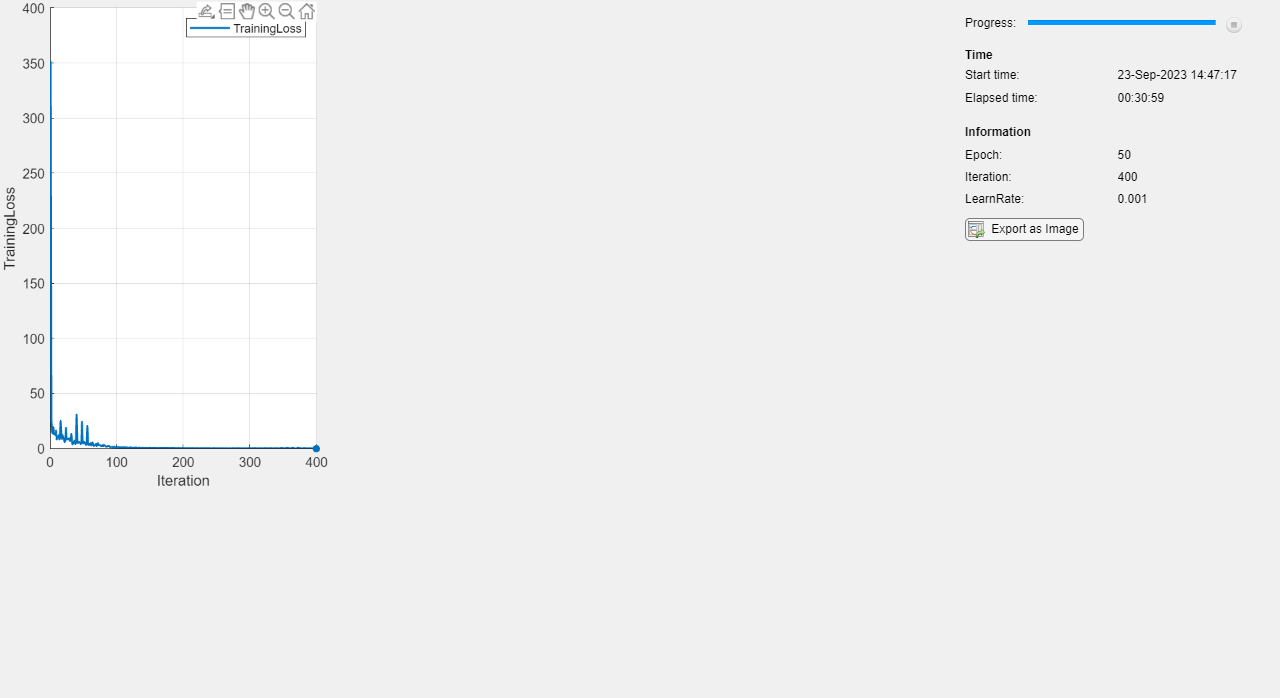

     50         400        00:30:49        0.001        0.02587   

*************************************************************************
Detector training complete.
*************************************************************************



% Train the YOLO v4 network.
detector = trainYOLOv4ObjectDetector(ds,preDetector,options);

save('aug4signs_yolov4_50e_n3.mat','detector');


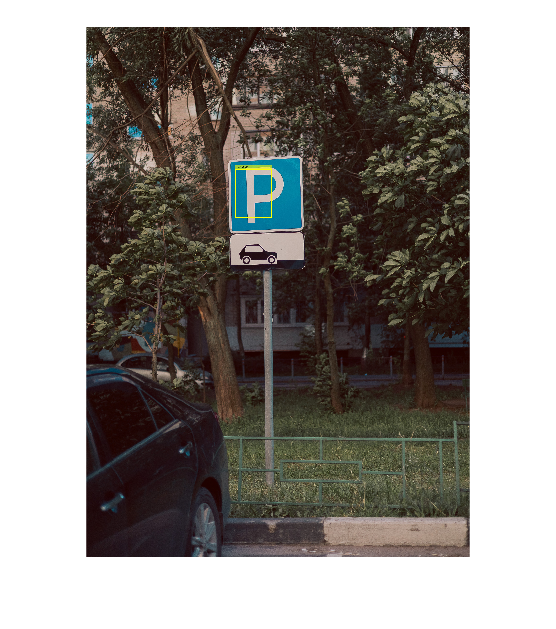

I = imread("C:\Users\Calm\Downloads\testing-signs\parking\parking (2).jpg");

[bboxes, scores, labels] = detect(detector,I,Threshold=0.05);
detectedImg = insertObjectAnnotation(I,"Rectangle",bboxes,labels,"LineWidth",8,"FontSize",24);
figure
imshow(detectedImg)

function data = preprocessData(data,targetSize)
for num = 1:size(data,1)
    I = data{num,1};
    imgSize = size(I);
    bboxes = data{num,2};
    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    data(num,1:2) = {I,bboxes};
end
end